# ELABORATO MATLAB

# LO BRUTTO FABIO / MAIONE PAOLO

## INTRODUZIONE

Lo scopo di questo elaborato è valutare le performance del Parallel Computing Toolbox di Matlab, per sfruttare il parallelismo messo a disposizione dal processore dual-core Intel Core i7-7500U e dalla GPU NVIDIA GeForce 940 MX. 

Per mostrare i vantaggi dell'elaborazione parallela su Matlab verranno implementati i seguenti programmi :

- Inizializzazione di una matrice;

- Generazione di un frattale;

- Prodotto riga per colonna tra due matrici.

### Inizializzazione di una matrice

Il seguente script inizializza una matrice NxM.

L'inizializzazione viene eseguita in due modi: sfruttando un `for` sequenziale e un `parfor` messo a disposizione dal Parallel Toolbox.

In particolare il `parfor` viene eseguito in un `parpool` (generato automaticamente) composto da 2 `worker`, che mappano i due core fisici del processore Intel.

Vengono eseguiti dei test al variare della dimensione della matrice e vengono infine mostrati i risultati in forma grafica.

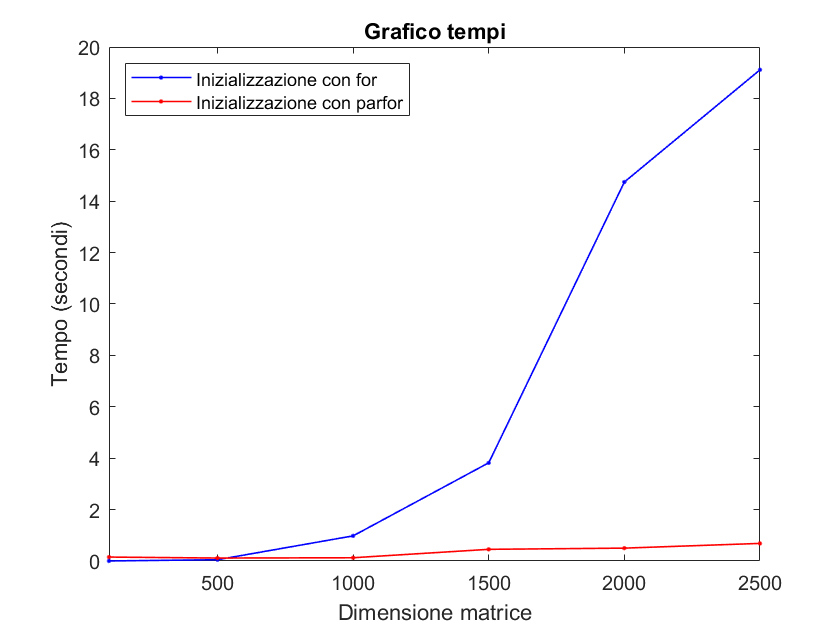

%esecuzione script
inizializzazione_matrici

### Generazione di un frattale

Il seguente script genera un frattale. A tal proposito si è scelto di utilizzare un esempio presentato al corso di Calcolo Numerico.

A differenza dello script precedentemente presentato si farà un confronto dei tempi tra esecuzione sequenziale sulla CPU e esecuzione parallela sulla GPU.

In particolare sono state definite due function julia_cpu.m e julia_gpu.m. Nel caso di julia_gpu.m, viene usato il comando `gpuArray` per allocare ed inizializzare direttamente sulla GPU i vettori, e il comando `gather` per restituire alla CPU il risultato della elaborazione.

Vengono eseguiti dei test al variare della granularità della griglia `N` e vengono infine mostrati i risultati in forma grafica.

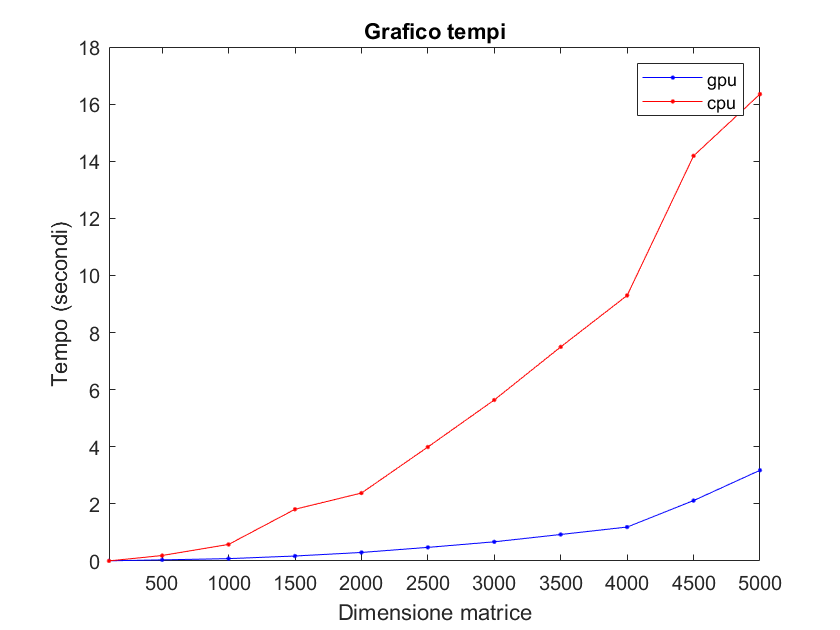

%esecuzione script
Frattale

### Prodotto tra due matrici

Il seguente script calcola il prodotto riga per colonne tra due matrici.

Come nel caso del frattale, vengono confrontati i tempi tra esecuzione sequenziale su CPU e esecuzione parallela su GPU.

Vengono eseguiti dei test al variare della dimensione delle due matrici e vengono infine mostrati i risultati in forma grafica.

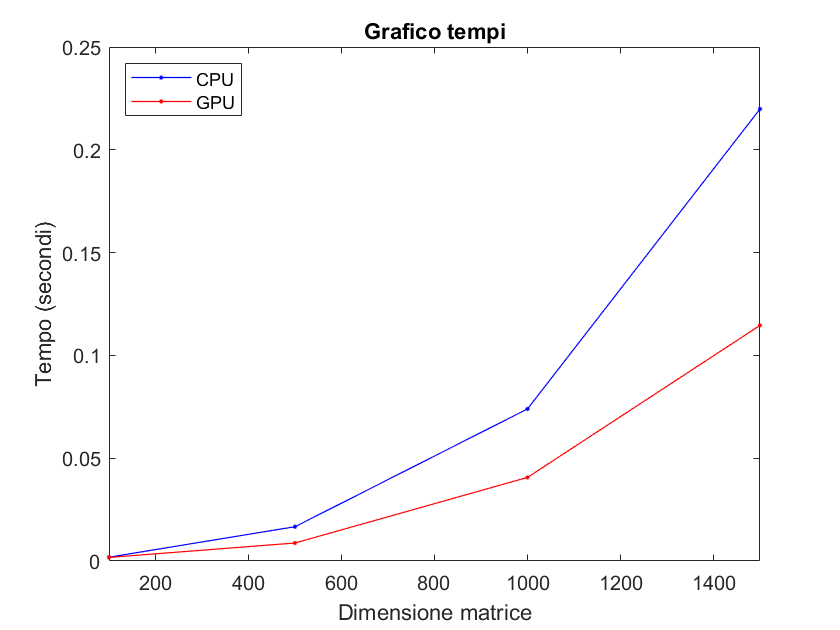

%esecuzione script
prodotto_matrici

### Conclusioni

Come si può notare il tempo di esecuzione nel caso parallelo (mediante parfor o mediante GPU) è nettamente inferiore al caso sequenziale, tranne, in alcuni casi, per dimensioni piccole del problema in esame.